clc;
clear all;
warning off;
tic
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb = [
      0      %A1
      0      %b1
      0      %A2
      0      %b2
      0       %Tp
      0       %Tf0
      0       %Tvl
      0       %Tv0
      0.85    %yita
     ]; 

ub = [
      0.3       %A1
      0.2       %b1
      0.5          %A2
      0.5       %b2
      3       %Tp
      6       %Tf0
      15      %Tvl
      10      %Tv0
      0.95    %yita
     ];    

Npara = length(lb); 

A1   = 0.165         ; A2   = 0.335         ;
b1   = 0.0455        ; b2   = 0.3           ;
Tp   = 1.5           ; Tf0  = 6             ;
Tvl  = 13            ; Tv0  = 6             ;
st   = 0.19          ; yita = 0.95          ;

para_init = [A1,b1,A2,b2,...
            Tp,Tf0,Tvl,Tv0,...
            yita];

%% ==================== 1. 工况设置 ============================
meanangle    = 15;
averageangle = 10;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

n_steps = conditions.n_steps;
w       = conditions.w;
dt      = conditions.dt;

## 4. 目标函数

fitnessFcn = @(param) fitness(param);
initial_fitness = fitness(para_init);
nonlcon = @(param) fitness_constraint(param, initial_fitness);

## 5. 全局优化，遗传算法配置 

globaloptions = optimoptions('ga',    ...
    'PopulationSize', 128,      ...     % 种群规模
    'MaxGenerations', 50,      ...     % 迭代次数
    'FunctionTolerance',1e-6,   ...    
    'ConstraintTolerance',1e-6, ...  
    'PlotFcn','gaplotrange',    ...     % 收敛曲线可视化
    'Display','iter',           ...   
    'InitialPopulationMatrix', para_init, ...
    'UseParallel',true);         

## 6. 运行进化算法寻优

fprintf('===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====\n'); 

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====



单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
正在使用 'Processes' 配置文件启动并行池(parpool)...
保留 ID 为 1 的作业，因为它们包含崩溃转储文件。
您可以使用 'delete(myCluster.Jobs)' 来删除使用配置文件 Processes 创建的所有作业。要创建 'myCluster'，请使用 'myCluster = parcluster('Processes')'。
2026-01-19 21:19:31: 已连接到 32 个并行池工作进程中的 15 个。
已连接到具有 32 个工作进程的并行池。

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           3132       2.87424            0      0
    2           6200       2.38399            0      0
    3           9268       2.38089            0      0
    4          12336       2.38083            0      0
    5          15404       2.38073            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。


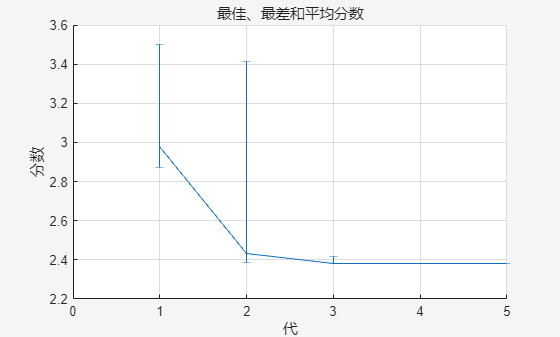

[para_global, fitness_opt] = ga(fitnessFcn, Npara, [], [], [], [], lb, ub, nonlcon, globaloptions);

fprintf('===== 优化完成！最优适应度值 = %.8f =====\n', fitness_opt);

===== 优化完成！最优适应度值 = 2.38072747 =====


## 7. 局部优化

fminconOpts = optimoptions('fmincon', ...
    'Algorithm', 'interior-point', ...
    'Display', 'iter', ... 
    'MaxFunctionEvaluations', 50, ... 
    'OptimalityTolerance', 1e-8, ...
    'StepTolerance', 1e-10,...
    'PlotFcn','optimplotfirstorderopt',...
    'UseParallel',true);

## 8. 运行局部最优化

fprintf('===== fmincon 局部优化开始 =====\n');

===== fmincon 局部优化开始 =====


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      10    2.380727e+00    0.000e+00    6.224e-01
    1      20    3.221000e+00    0.000e+00    4.241e+01    3.487e-01
    2      41    3.383999e+00    0.000e+00    3.711e+01    1.453e-01
    3      56    3.385962e+00    0.000e+00    3.178e+00    1.198e-01

求解器过早停止。

fmincon 已停止，因为它超过函数计算限制，
options.MaxFunctionEvaluations = 5.000000e+01。



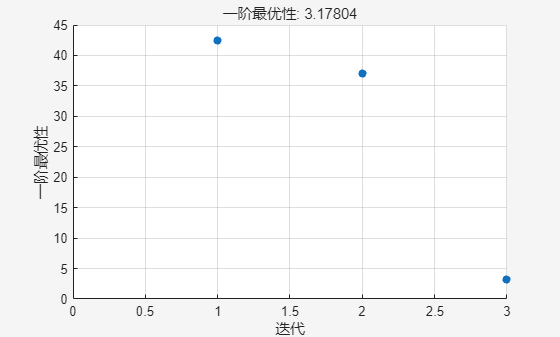

para1 = para_global;  % 使用 GA 的最优解作为初始值
[para_local, f_opt] = fmincon(fitnessFcn, para1, [], [], [], [], lb, ub, nonlcon, fminconOpts);

fprintf('===== 局部优化完成：最优适应度值 = %.10f =====\n', f_opt);

===== 局部优化完成：最优适应度值 = 3.3859616612 =====


## 7. 结果输出+保存

para_label = {'A1','b1','A2','b2','Tp','Tf0','Tvl','Tv0','yita'};
fprintf('\n==================== 原始参数 ↔ 优化后最优参数 对比表 ====================\n');


==================== 原始参数 ↔ 优化后最优参数 对比表 ====================


fprintf('原始适应度=%.6f | 优化适应度=%.6f\n', fitness(para_init), fitness(para_local));

原始适应度=21.001085 | 优化适应度=3.385962


for i = 1:Npara
    fprintf('%5s : 原始值=%.6f | 优化值=%.6f\n', para_label{i}, para_init(i), para_local(i));
end

   A1 : 原始值=0.165000 | 优化值=0.040047
   b1 : 原始值=0.045500 | 优化值=0.112948
   A2 : 原始值=0.335000 | 优化值=0.488129
   b2 : 原始值=0.300000 | 优化值=0.435412
   Tp : 原始值=1.500000 | 优化值=2.357909
  Tf0 : 原始值=6.000000 | 优化值=5.369212
  Tvl : 原始值=13.000000 | 优化值=14.174294
  Tv0 : 原始值=6.000000 | 优化值=9.705222
 yita : 原始值=0.950000 | 优化值=0.888903


[A1,b1,A2,b2,Tp,Tf0,Tvl,Tv0,yita] = deal(para_local(:));
save('BL模型_CFD拟合_最终优化参数.mat','para_local','fitness_opt');
fprintf('\n优化结果已保存至：BL模型_CFD拟合_最终优化参数.mat\n');


优化结果已保存至：BL模型_CFD拟合_最终优化参数.mat


toc

历时 5164.546576 秒。


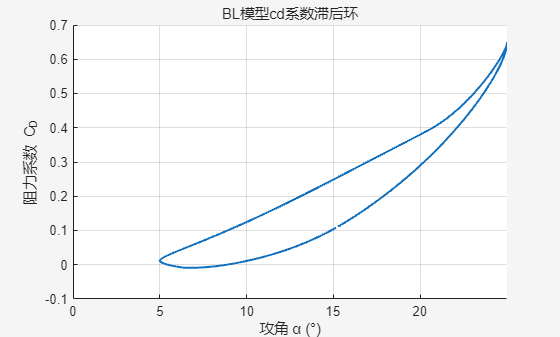

%% ===================== 2. 计算BL模型的输出值 Cl_BL / Cm_BL =====================
[CC_total,CN_total,CM_total,CD,CL,CM,a] = cal_DS(para_local,conditions,airfoildata);

% CFD数据
[a0, Cl_CFD,Cd_CFD,Cm_CFD] = get_CFDdata('FFA_W3_211_rlt_20.txt');

%% 5. 总气动力转换
% 升力、阻力转换（三角函数投影）

start = 7.5;
last  = 8.5;
idx_s = 2*pi/w*start/dt;
idx_l = 2*pi/w*last/dt;

plot(rad2deg(a(idx_s:idx_l)), CL(idx_s:idx_l), 'LineWidth',1.5);
xlabel('攻角 α (°)'); ylabel('升力系数 C_L');
title('BL模型cl系数滞后环'); grid on;


plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), 'LineWidth',1.5);
xlabel('攻角 α (°)'); ylabel('阻力系数 C_D');
title('BL模型cd系数滞后环');grid on;

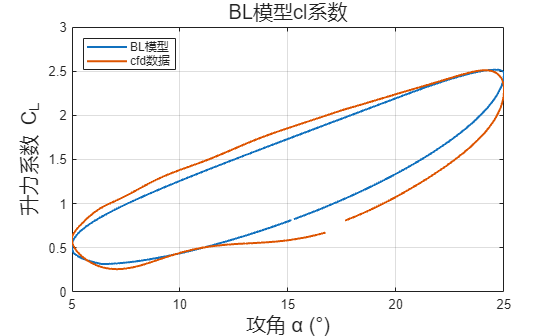


%openfast数据----------------------------------------------

fastcl = readmatrix("openfast_1hz_5_cl.txt");
fastcl(:,2) = smooth(fastcl(:,2));
fast_a1 = fastcl(:,1);
fast_cl = fastcl(:,2);

fastcd = readmatrix("openfast_1hz_5_cd.txt");
fastcd(:,2) = smooth(fastcd(:,2));
fast_a2 = fastcd(:,1);
fast_cd = fastcd(:,2);

%CFD数据---------------------------------------------------
data = readmatrix("FFA_W3_211.txt");
figure
[a1,cl] = drawCoffeint('cl_211_0.31_20.out',meanangle,averageangle);
plot(rad2deg(a(idx_s:idx_l)), CL(idx_s:idx_l),a1,cl, 'LineWidth',1.5);
xlabel('攻角 α (°)','FontSize',15); 
ylabel('升力系数 C_L','FontSize',15);
title('BL模型cl系数','FontSize',15); grid on;
legend('BL模型','cfd数据','Location','northwest')
saveas(gcf, ['cl_compare','.png']);
exportgraphics(gcf,'cl_compare.pdf','ContentType', 'vector')

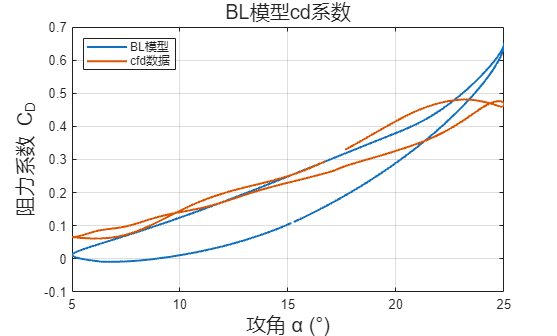


figure
[a2,cd] = drawCoffeint('cd_211_0.31_20.out',meanangle,averageangle);
plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), a2,cd,'LineWidth',1.5);
xlabel('攻角 α (°)','FontSize',15); 
ylabel('阻力系数 C_D','FontSize',15);
title('BL模型cd系数','FontSize',15); grid on;
legend('BL模型','cfd数据','Location','northwest')
saveas(gcf, ['cd_compare','.png']);
exportgraphics(gcf,'cd_compare.pdf','ContentType', 'vector')


% figure
% [a3,cm] = drawCoffeint('cm_211_0.31_20.out',meanangle,averageangle);
% plot(rad2deg(a(idx_s:idx_l)), CM_total(idx_s:idx_l),data(43:72,1),data(43:72,4),a3,cm, 'LineWidth',1.5);
% xlabel('攻角 α (°)','FontSize',15); 
% ylabel('力矩系数 C_M','FontSize',15);
% title('BL模型cm系数','FontSize',15); grid on;
% legend('BL模型','升阻力数据','CFD结果','Location','northwest')
% saveas(gcf, ['cm_compare','.png']);
% exportgraphics(gcf,'cm_compare.pdf','ContentType', 'vector')

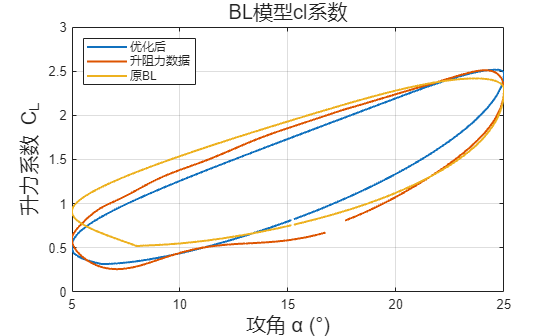

[CC_init,CN_init,CM_init,CD_init,CL_init,CM_init,a_init] = cal_DS(para_init,conditions,airfoildata,st);

figure
plot(rad2deg(a(idx_s:idx_l)), CL(idx_s:idx_l),a1,cl,rad2deg(a_init(idx_s:idx_l)),CL_init(idx_s:idx_l), 'LineWidth',1.5);
xlabel('攻角 α (°)','FontSize',15); 
ylabel('升力系数 C_L','FontSize',15);
title('BL模型cl系数','FontSize',15); grid on;
legend('优化后','升阻力数据','原BL','Location','northwest')

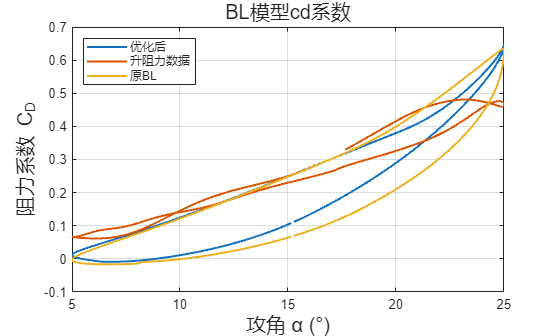


figure
plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), a2,cd,rad2deg(a_init(idx_s:idx_l)),CD_init(idx_s:idx_l),'LineWidth',1.5);
xlabel('攻角 α (°)','FontSize',15); 
ylabel('阻力系数 C_D','FontSize',15);
title('BL模型cd系数','FontSize',15); grid on;
legend('优化后','升阻力数据','原BL','openfast','Location','northwest')